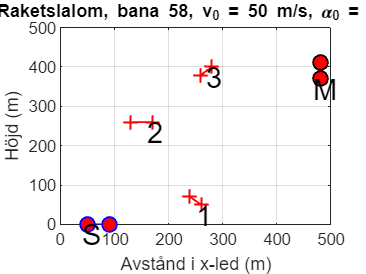

% Clear variables and command window
clear
clf

% Load data
load bana-58.mat

% Plot the track
plotTrack(portx, porty, ver, v0,a0);

hold on
starthastighet = 50;

hastighet_xled = starthastighet*cos(pi/3);
hastighet_yled = starthastighet*sin(pi/3);
startvinkel = 60;
tspan = [0,50];
y0 = [70, hastighet_xled, 0, hastighet_yled];

[t,y] = ode45(@rocketEquation, tspan, y0);

plot(y(:,1),y(:,3))


vinklar = [pi/2 pi/2 5*pi/4 5*pi/4 3*pi/2 3*pi/2 7*pi/4 7*pi/4 3*pi/2 3*pi/2 pi pi 5*pi/4 5*pi/4];

vinklarTid = [0 5 5 8 8 13 13 17 17 26 26 33 33 40];
vinklar = rad2deg(vinklar)

vinklar =     90    90   225   225   270   270   315   315   270   270   180   180   225   225


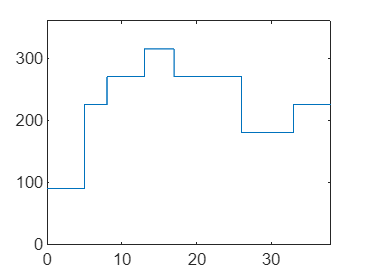

plot(vinklarTid, vinklar);



ylim([0 360])
xlim([0 38])